setup() ;

## Part 2.1: Backward mode verification

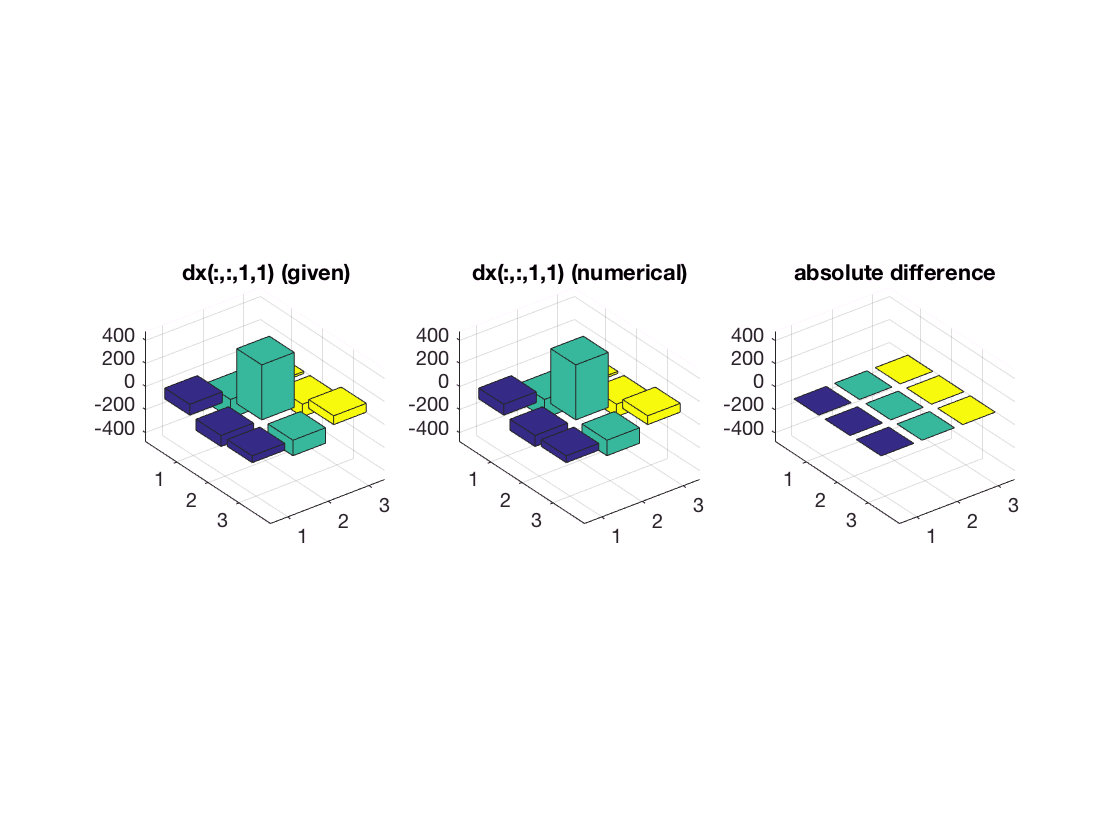

% Create a random input image batch
x = randn(10, 10, 1, 2, 'single') ;

% Define a filter
w = single([
  0 -1 -0
  -1 4 -1
  0 -1 0]) ;

% Forward mode: evaluate the convolution
y = vl_nnconv(x, w, []) ;

% Pick a random projection tensor
p = y(:, :, 1, :);

% Backward mode: projected derivatives
[dx,dw] = vl_nnconv(x, w, [], p) ;

% Check the derivative numerically
figure(21) ; clf('reset') ;
set(gcf, 'name', 'Part 2.1: single layer backrpop') ;
checkDerivativeNumerically(@(x) proj(p, vl_nnconv(x, w, [])), x, dx) ;
%check based on w
checkDerivativeNumerically(@(w) proj(p, vl_nnconv(x, w, [])), w, dw) ;

## Part 2.2: Backpropagation

% Create a random input image batch
x = randn(10, 10, 1, 2, 'single') ;

% Forward mode: evaluate the conv follwed by ReLU
y = vl_nnconv(x, w, []) ;
z = vl_nnrelu(y) ;

% Pick a random projection tensor

p = randn(size(z), 'single') ;
p = z(:, :, 1, :);

% Backward mode: projected derivatives
dy = vl_nnrelu(z, p) ;
[dx,dw] = vl_nnconv(x, w, [], dy) ;

% Check the derivative numerically
figure(22) ; clf('reset') ;
set(gcf, 'name', 'Part 2.2: two layers backrpop') ;
func = @(x) proj(p, vl_nnrelu(vl_nnconv(x, w, []))) ;
% checkDerivativeNumerically(func, x, dx) ;

## Part 2.3: Design and verify your own layer

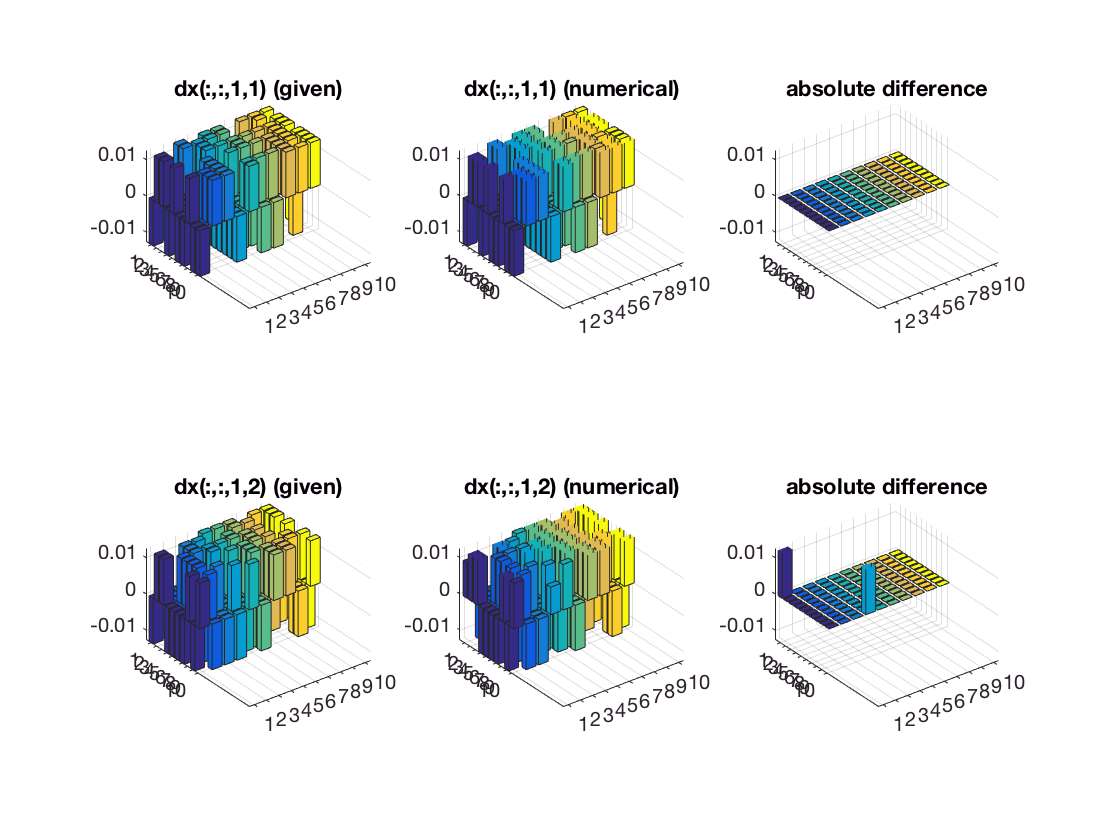

x0 = randn(size(x), 'single') ;

%forward = @l2LossForward; backward = @l2LossBackward ;

% Uncomment the followung line to test your L1 loss implementation
forward = @l1LossForward; backward = @l1LossBackward ;

y = forward(x, x0) ;

p = randn(size(y), 'single') ;
dx = backward(x, x0, p) ;

% Check the derivative numerically
figure(23) ; clf('reset') ;
set(gcf, 'name', 'Part 2.3: custom loss layer') ;
func = @(x) proj(p, forward(x, x0)) ;
checkDerivativeNumerically(func, x, dx) ;